# Ersatzschaltbildrechnung

## Einführung

Das *Livescript ***Ersatzschaltbildrechnung** simuliert den Einsatz einer Batterie unter bestimmten Umgebungseinflüssen. Im nachfolgenden können Verbraucher zugeschaltet und deren Auswirkungen auf das Bordnetz beobachtet werden.

Wie in der nachfolgenden Grafik zu erkennen, darf die Batteriespannung gewisse Werte nicht über bzw. unterschreiten. Wird die Batterie kurzzeitig über 20V (oder 16V dauerhaft) gebracht, beschädigt man die Batterie dauerhaft, sodass sich die Lebensdauer verkürzt. Fällt die Batterie unter 9V kann zum Beispiel der Motor nicht mehr gestartet werden, ebenfalls kann es dazu kommen, dass die Batterie beschädigt wird.

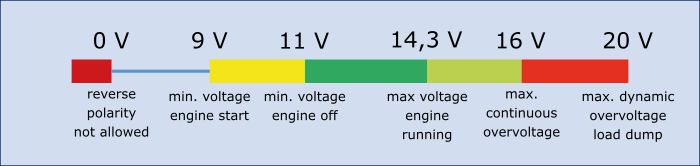

**Allgemeiner Hinweis:**

 *Wenn Sie Kommazahlen eingeben, bitte darauf achten, dass diese in Matlab mit einem '.' eingegeben werden*

## 1. Eingabe der Batteriedaten

### 1.1 Innenwiderstand über Entladung der Batterie 

*Das Bordnetz hat eine nomielle Spannung von 12V, allerdings kann dies je nach Betriebszustand der Batterie schwanken, wie in der folgenden Grafik beobachtet werden kann.*

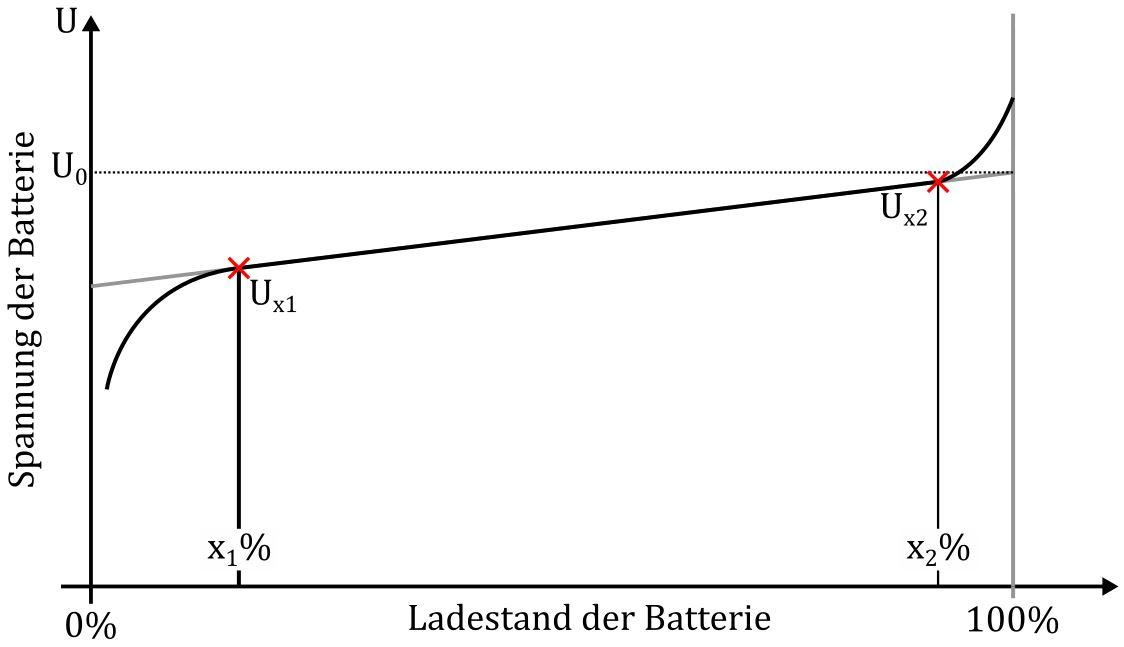

`Im folgenden wird die Spannung nur im linearen Bereich betrachtet`

Zunächst ist die Eingabe der Stützstellen bei x1% und x2% gefordert:

%Preset für das 'configurable subsystem' in Simulink
SubsystemVerbraucherwiderstand = Simulink.Variant('Mode == 1');
SubsystemVerbraucherleistung = Simulink.Variant('Mode == 2');
%Eingabe der Stützstellen bei x1 und x1 Prozent
x1 = 10; U_x1 = 12;
x2 = 90; U_x2 = 14;
%Geradengleichung für die Spannung aufstellen y=m*x+b
gerade_batteriespannung = (U_x2-U_x1)/(x2-x1);
x_ladestand = (0:10:100);
y_ladestand = gerade_batteriespannung*x_ladestand+U_x1-(gerade_batteriespannung*x1);
%clf
%plot(x_ladestand,y_ladestand)
fprintf('------------------------------------------------------------------------------------------')

------------------------------------------------------------------------------------------

Ladestand = 10;
%Berechnen des tatsächlichen Ladestands
U_real = gerade_batteriespannung*Ladestand+U_x1-(gerade_batteriespannung*x1);
R_i = 20e-3;
fprintf('Die sich daraus ergebende tatsächliche Batteriespannung beträgt: %4.2f V\n', U_real')

Die sich daraus ergebende tatsächliche Batteriespannung beträgt: 12.00 V


U_b0 = U_real;

### 1.2 Innenwiderstand über Temperatur und Entladung

Im folgenden Diagramm wird auch die nicht nur der Ladestand der Batterie für die Berechnung des Innenwiderstands berücksichtigt, sondern auch die Außentemperatur. Durch auswählen der Gegebenheiten, wird ein Arbeitspunkt für die spätere Rechnung bestimmt.

Durch setzten des Häkchens wird** 1.1** deaktiviert und der Innenwiderstand unter Berücksichtigung der Außentemperatur berechnet.

h_temp = true;

`Achtung: Nicht für alle Aussentemperaturen ist jede Entladetiefe möglich!`

`Die Batteriespannung wird in diesem Abschnitt als 12V angenommen`

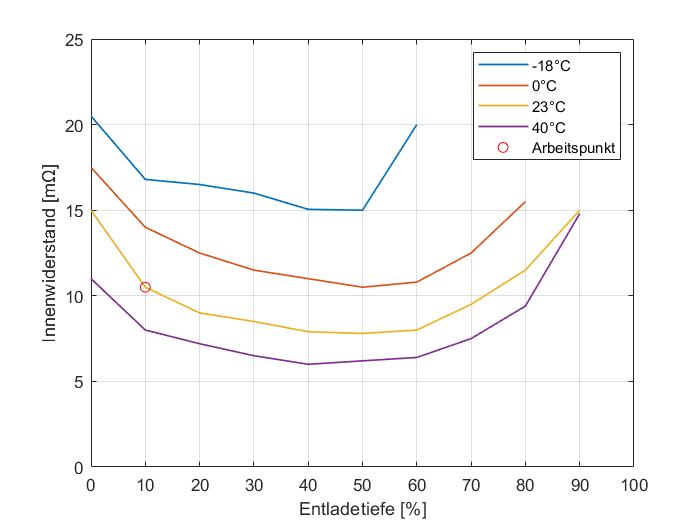

Der Innenwiderstand der Batterie beträgt:


0.01 Ω


Aussentemperatur =  23;
Entladetiefe =  10;
clf
%plot der Innenwiderstands-Kennlinien
x18 = (0:10:60);
x0 = (0:10:80);
x = (0:10:90);
y18 = [20.5, 16.8, 16.5, 16, 15.05, 15, 20];
y0 = [17.5, 14, 12.5, 11.5, 11, 10.5, 10.8, 12.5, 15.5];
y23 = [15, 10.5, 9, 8.5, 7.9, 7.8, 8, 9.5, 11.5, 15];
y40 = [11, 8, 7.2, 6.5, 6, 6.2, 6.4, 7.5, 9.4, 14.8];
plot(x18,y18, x0, y0, x, y23, x, y40, 'LineWidth',1)
xlim([0.0 100.0])
ylim([0.0 25.0])
grid on
hold on
%Achsenbeschriftung
xlabel('Entladetiefe [%]')
ylabel('Innenwiderstand [mΩ]')
legend('-18°C','0°C','23°C','40°C')
if h_temp == 1
%zurücksetzen der Parameter
    clear r
    clear U0
    U_b0 = 12;
t = Entladetiefe/10+1;
%feststellen der aktuellen Kurve
switch Aussentemperatur
    case -18
        Innenwiderstand = y18(t);
    case 0
        Innenwiderstand = y0(t);
    case 23
        Innenwiderstand = y23(t);
    case 40
        Innenwiderstand = y40(t);
end
R_i= Innenwiderstand*0.001;
plot(Entladetiefe,R_i*1000,'ro');                                         %plotten des AP
legend('-18°C','0°C','23°C','40°C','Arbeitspunkt')
fprintf('Der Innenwiderstand der Batterie beträgt:\n')  
fprintf('%4.2f Ω\n',R_i)
end

## 2. Verbraucher 

### 2.1 Verbraucher über Leistung 

Zunächst kann* eine *der folgenden zwei Fahrsituationen ausgewählt werden:

#### Anwendungsfall 1:

Sie fahren an einem Nachmittag im Frühling mit Freunden in die Stadt, dabei sind folgende Verbraucher standardmäßig eingeschaltet: Zündung (20W), Kraftstoffpumpe (50W), Mototronik (200W), sowie die Beleuchtungseinrichtung mit 20W.

#### Anwendungsfall 2:

Sie fahren am frühen Morgen im Winter auf den Berg zum Skifahren, dabei sind folgende Verbraucher standardmäßig eingeschaltet: Verbraucher aus Fahrsituation 1 + Abblendlicht (90W), Heizung (50W), Heckscheibenheizung (60W) und Sitzheizung (10W)

*Angegeben wird immer die mittlere Leistung der Verbraucher*

Fahrsituation = 0;
Mode = 2;                      %Subsystem Simulink festlegen
%feststellen der Fahrsituation
switch Fahrsituation
    case 0
        P_fs = 290;
    case 1
        P_fs = 500;
end

Hier können zusätzlich zur ausgewählten Fahrsituation noch eigene Verbraucher aktiviert werden:

%ggf. zusätzliche Verbraucher
Sitzmassage = false;
if Sitzmassage==1
    fprintf('Die Sitzmassage benötigt eine mittlere Leistung von 40W') 
    sm = 40;
else
    sm = 0;
end
Mediasystem = false;
if Mediasystem==1
    fprintf('Das Mediasystem benötigt eine mittlere Leistung von 20W') 
      ms=20;
else
    ms=0;
end
%addieren der gesamten Verbraucherleistung
Pges = P_fs+ sm + ms;

Die addierte mittlere Leistung aller aktivierten Verbraucher beträgt:

fprintf('%4.0f Watt', Pges)

 290 Watt

format long                                 %genauere Berechnung der Werte
% nicht relevant, da größerer Strom
% I_1 = (U0+sqrt((-U0)^2-4*Ri*Pges))/(2*Ri);4
I_2 = (U_b0-sqrt((-U_b0)^2-4*R_i*Pges))/(2*R_i);
I = I_2;
Rv = Pges/I^2;
Ub = I*Rv;

### 2.2 Individueller Verbraucherwiderstand

Durch setzten des Häkchens wird** 2.1** deaktiviert und der Verbraucherwiderstand kann manuell ausgewählt werden.

Verbraucherwiderstand =true;
if Verbraucherwiderstand==1 
Mode = 1;                       %Subsystem Simulink festlegen                  
%zurücksetzen der Parameter 
    clear Rv_1
    clear Rv_2
    clear Rv
    clear I
    clear Pges
Rv =0.3; %Innenwiderstand festlegen
%Berechnung der sich daraus ergebenden Klemmenspannung, Strom und Leistung
Ub = U_b0*(Rv/(Rv+R_i));
I = Ub/Rv;
Pges = Ub*I;
end

## **3. Ersatzschaltbild**

fprintf('Batteriespannung: %4.2f V', U_b0)

Batteriespannung: 12.00 V

fprintf('Innenwiderstand = %4.2f mΩ', R_i);

Innenwiderstand = 0.01 mΩ

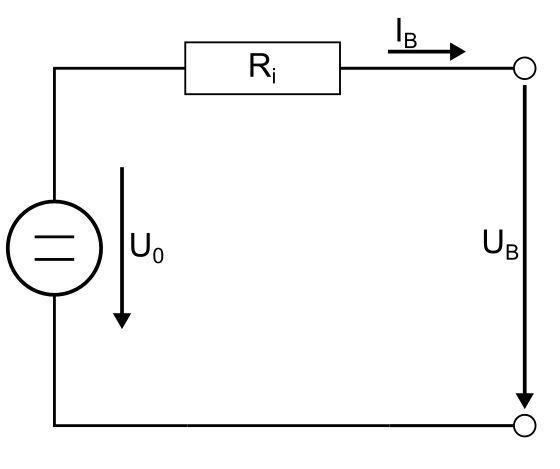 

**Berechnung des Verbraucherwiderstands (*****Festlegung der Verbraucher*****)**


$$\mathrm{I}:I_B =\frac{U_0 }{R_i +R_v }\;$$



$$\textrm{II}:R_V =\frac{P}{{I_B }^2 }$$



$$\;\textrm{II}\;\textrm{in}\;\mathrm{I}\;\textrm{einsetzen}:I=\frac{U_0 }{R_i +\frac{P}{{I_B }^2 }}\;$$



$$I_{B1,2} \;=\frac{U_0 \underline{+} \sqrt{{\left({-U}_0 \right)}^2 -4*R_i *P}}{2*R_i }$$


Der *kleinere Strom* ist hier die *richtige Lösung*, da es besser ist mit kleinerem Strom und hoher Spannung zu entladen.

*Wurde der Vebraucherwiderstand individuell festgelegt, beginnt die Rechnung hier:*


$$\textrm{Spannungsteilerformel}:U_B =U_0 *\frac{R_v }{R_v +R_i }$$



$$\textrm{Stromfluss}:I_B =\frac{R_v }{U_B }$$


fprintf('Die Klemmenspannung beträgt: %4.4f V', Ub)

Die Klemmenspannung beträgt: 11.5942 V

fprintf('Der Stromfluss beträgt: %4.4f A', I)

Der Stromfluss beträgt: 38.6473 A

%fprintf('Der Verbraucherwiderstand beträgt: %4.4f Ω', Rv)
fprintf('Die Leistung des Verbrauchers beträgt: %4.2f W', Pges)

Die Leistung des Verbrauchers beträgt: 448.09 W

## 4. Batteriekennlinie

Die Kennlinie der Spannungsquelle wird wie folgt berechnet:


$$\textrm{Schnittpunkt}\;\textrm{mit}\;\textrm{der}\;X-\textrm{Achse}\;\textrm{ist}\;\textrm{die}\;U_0 \;\textrm{Spannung}\;\textrm{der}\;\textrm{Batterie}$$



$${\textrm{Schnittpunkt}\;\textrm{mit}\;\textrm{der}\;Y-\textrm{Achse}\;\textrm{ist}\;\textrm{der}\;\textrm{Kurzschlussstrom}\;I}_K =\frac{U_0 }{R_i }$$


Das verbinden der beiden Punkte ergibt die Kennlinie der Spannungsquelle (blau dargestellt).

Der *rote Kreis* markiert den *aktuellen Arbeitspunkt* der Batterie.

Die farbigen Bereiche sind denen aus der ***Einführung*** zu entnehmen.

u= [U_b0, 0];                     %Schnittpunkt mit der X-Achse
i = [0, U_b0/R_i];                 %Schnittpunkt mit der Y-Achse
figure
plot(i,u,'LineWidth',2)         %Batteriekennlinie plotten
if I-5<0                        %Skalieren der X-Achse
    x_grenz = 0;
else
    x_grenz = I-5;
end
xlim([x_grenz I+5])    
ylim([8.0 14.3])                %Skalieren der Y-Achse
grid on
hold on
%Arbeitsbereiche markieren
rot=fill([I-5 I+5 I+5 I-5],[0 0 9 9],'red','FaceAlpha',0.2,'EdgeColor','none');
gelb = fill([I-5 I+5 I+5 I-5],[9 9 11 11],'yellow','FaceAlpha',0.2,'EdgeColor','none');
gruen = fill([I-5 I+5 I+5 I-5],[11 11 14.3 14.3],'green','FaceAlpha',0.2,'EdgeColor','none');
xlabel('Strom [A]')             %X-Achsenbeschriftung
ylabel('Spannung [V]')          %Y-Achsenbeschriftung
if Verbraucherwiderstand == 1   %Kennlinie falls Verbraucherwiderstand aktiviert  
is = (0:0.001:250);
Rges = R_i+Rv;
wk = Rges*is;
plot(is,wk,'LineWidth',2)
fprintf('Die orangene Kennlinie ist die Verbraucherkennlinie, kennt man diese Kennlinie,')
fprintf('so kann man ohne Berechnungen den sich ergebenden Strom und die Klemmenspannung')
fprintf('aus dem Schnittpunkt mit der Batteriekennlinie bestimmen')
end

Die orangene Kennlinie ist die Verbraucherkennlinie, kennt man diese Kennlinie,

so kann man ohne Berechnungen den sich ergebenden Strom und die Klemmenspannung

aus dem Schnittpunkt mit der Batteriekennlinie bestimmen

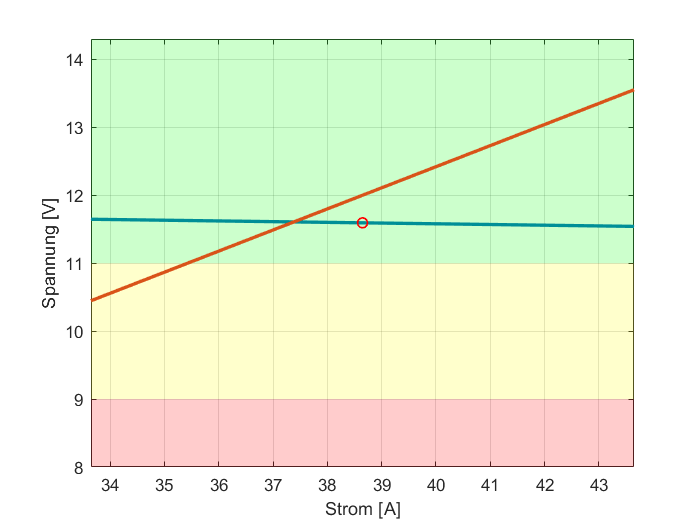

hold on
plot(I, Ub, 'ro','LineWidth',1) %Arbeitspunkt der Batterie plotten

## 5. Gleichstrommotor

Da ihre Freundin auch fahren möchte, steht das Auto nun am Seitenrand zum Fahrerwechsel (alle obigen Verbraucher sind deaktiviert). Nach dem einsteigen (5sek delay) betätigt sie die elektrische Sitzverstellung. Im folgenden Abschnitt kann nun die Auswirkung auf das Bordnetz beobachtet werden.

R_A = 3.98;
L = 2.3;
c_Mo = 0.027;
L = L * 0.001;
J_T = 3.3*10^-6; 

*Variieren Sie nun das Lastmoment und beobachten Sie, die Drehzahlveränderung. *

Welche charakteristischen Punkte bekommen Sie hier?

*Nach jeder Änderung muss in ****Simulink**** die 'run'-Taste betätigt werden*

M_L = 0.036;
Button_Loesung =  false;
if Button_Loesung == 1
fprintf('Wird das Motormoment auf 0 gesetzt erhält man die Leerlaufdrehzahl')
fprintf('Wird das Motormoment maximal, so erhält man das Stillstandsmoment mit n=0')
end
figure
plot(out.Klemmenspannung_Simulink)

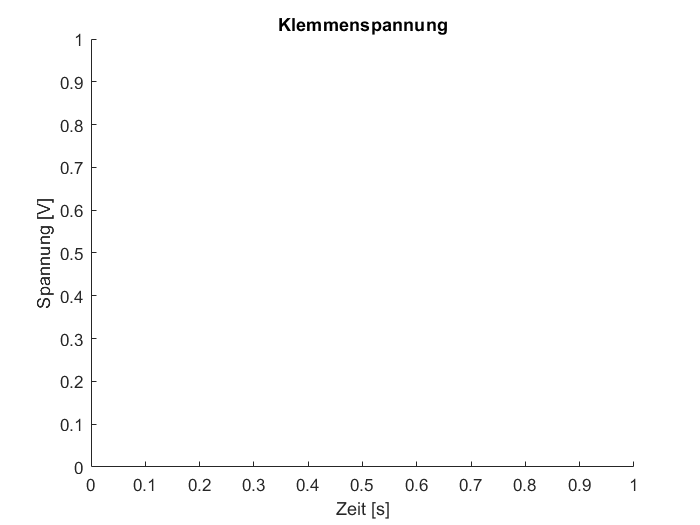

title('Klemmenspannung')
xlabel('Zeit [s]')             %X-Achsenbeschriftung
ylabel('Spannung [V]')          %Y-Achsenbeschriftung

figure
plot(out.Motordrehzahl_Simulink)

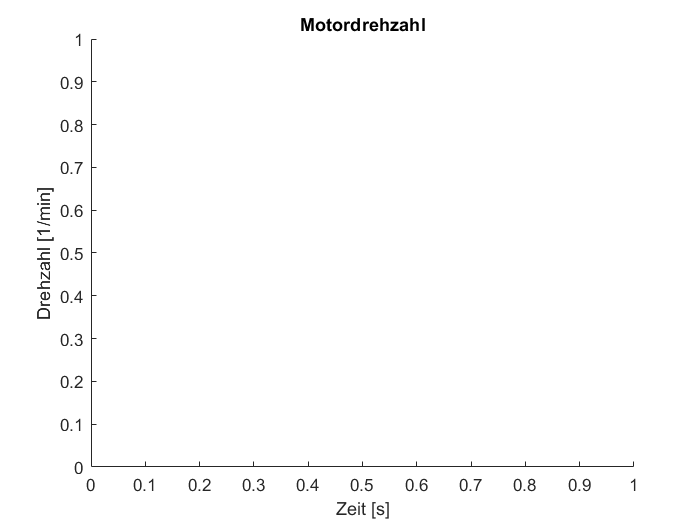

title('Motordrehzahl')
xlabel('Zeit [s]')             %X-Achsenbeschriftung
ylabel('Drehzahl [1/min]')          %Y-Achsenbeschriftung